[xg,yg] = meshgrid(-3:0.25:3);
xg = xg(:);
yg = yg(:);

Create a unit disk. Remove all the mesh grid points that fall inside the unit disk, and include the unit disk points.

% t = (pi/24:pi/24:2*pi)';
% x = cos(t);
% y = sin(t);
% circShp = alphaShape(x,y,2);
% in = inShape(circShp,xg,yg);
% xg = [xg(~in); cos(t)];
% yg = [yg(~in); sin(t)]; 

Create 3-D copies of the remaining mesh grid points, with the *z*-coordinates ranging from 0 through 1. Combine the points into an `alphaShape` object.

zg = ones(numel(xg),1);
xg = repmat(xg,5,1);
yg = repmat(yg,5,1);
zg = zg*(0:.25:1);
zg = zg(:);
shp = alphaShape(xg,yg,zg);

Generate a surface mesh of the `alphaShape` object.

[elements,nodes] = boundaryFacets(shp);

Create an `fegeometry` object from the surface mesh.

gm = fegeometry(nodes,elements)

gm =   fegeometry with properties:

       NumFaces: 6
       NumEdges: 12
    NumVertices: 8
       NumCells: 1
       Vertices: [8×3 double]
           Mesh: []


For a 3-D geometry created from the surface mesh, the `Mesh` property remains empty. To use the geometry in an analysis, generate a mesh.

gm = generateMesh(gm, 'GeometricOrder','linear', 'Hmax',0.8, 'Hmin',0.5);
gm.Mesh

ans =   FEMesh with properties:

             Nodes: [3×227 double]
          Elements: [4×658 double]
    MaxElementSize: 0.8000
    MinElementSize: 0.5000
     MeshGradation: 1.5000
    GeometricOrder: 'linear'


Plot the geometry with the face labels.

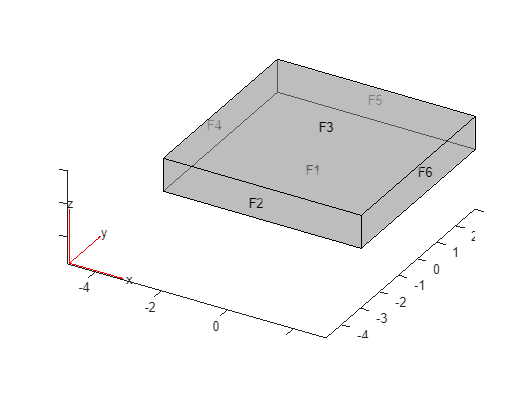

pdegplot(gm,FaceLabels="on",FaceAlpha=0.5);

Plot the mesh.

mesh= generateMesh(gm)

mesh =   fegeometry with properties:

       NumFaces: 6
       NumEdges: 12
    NumVertices: 8
       NumCells: 1
       Vertices: [8×3 double]
           Mesh: [1×1 FEMesh]


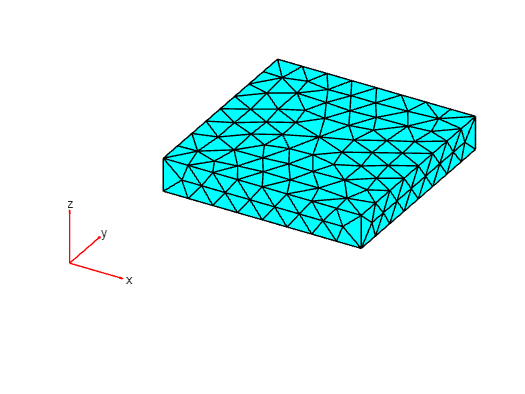

figure
pdemesh(gm);

get Nodes on Face

% nodesOnFace = findNodes(gm.Mesh, 'region', 'Face', F7)

get the matrix of Element

Mesh_Mt = (ans.Elements)'

Mesh_Mt =    204    19   120   119
    19   120    18    78
    39   129    38   121
   180   139   181    54
     9     4    84   191
   128   129    39   121
   192    81    15     5
   210   156   136   137
   128   204    97    78
   192   200     5     6


get the matrix of Nodes

Node_Mt = (ans.Nodes)'

Node_Mt =    -3.0000   -3.0000    1.0000
   -3.0000   -3.0000         0
   -3.0000    3.0000    1.0000
   -3.0000    3.0000         0
    3.0000    3.0000         0
    3.0000    3.0000    1.0000
    3.0000   -3.0000    1.0000
    3.0000   -3.0000         0
   -2.2500    3.0000         0
   -1.5000    3.0000         0


Calculate the matrix M_local at each element and calculate the Matrix M_total in $$\Omega$$

M_total = zeros(size(Node_Mt,1), size(Node_Mt,1));
M_local = zeros(4,4);
for i=1 : size(Mesh_Mt,1)
% i=3
    %syms g1 g2 g3 g4
    %g = [g1 g2 g3 g4]
    g = Mesh_Mt(i, :);
    g1 = Node_Mt(g(1),:);
    g2 = Node_Mt(g(2),:);
    g3 = Node_Mt(g(3),:);
    g4 = Node_Mt(g(4),:);
    % thay thế các điểm g1, g2, g3, g4 thành các điểm A_1, A_2, A_3, A_4
    syms x1 y1 z1 x2 y2 z2 x3 y3 z3 x4 y4 z4 
    x1 = g1(1); y1= g1(2) ; z1 = g1(3); 
    x2 = g2(1); y2= g2(2) ; z2 = g2(3); 
    x3 = g3(1); y3= g3(2) ; z3 = g3(3); 
    x4 = g4(1); y4= g4(2) ; z4 = g4(3); 

    P = [1 x1 y1 z1;...
         1 x2 y2 z2;...
         1 x3 y3 z3;...
         1 x4 y4 z4];
    Q = inv(P);
                %{
                P1 = [1 g1 ; ...
                      1 g2 ; ...
                      1 g3 ; ...
                      1 g4]
                Q1 = inv(P1)
                Q- Q1
                J = [ 
                    ] 
                %}
    % Khi chuyển hệ tọa độ ban đầu sang hệ mới và tính tích phân ta thu
    % được các công thức tính tích phân ứng với từng phi_i*phi_j, 
    % ma trận M_local(4,4) là ma trận đối xứng
    % Tính các tích phân để đưa vào M_local
    % Tích phân trên miền e của phi_1*phi_1
    M_local(1,1) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_1*phi_2 = phi_2*phi_1
    M_local(1,2) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_1*phi_3 = phi_3*phi_1
    M_local(1,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_1*phi_4 = phi_4*phi_1
    M_local(1,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_2*phi_2 
    M_local(2,2) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_2*phi_3 = phi_3*phi_2
    M_local(2,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_2*phi_4 = phi_4*phi_2
    M_local(2,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_3*phi_3 
    M_local(3,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_3*phi_4 = phi_4*phi_3
    M_local(3,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_4*phi_4
    M_local(4,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;

    M_local = M_local + (M_local)';
    M_local = M_local -0.5* diag(diag(M_local));
    M_total(g,g) = M_total(g,g) + M_local;
    % Gán các giá trị vào ma trận M_local
    %M_local(g(1),g(1))= Ans11; M_local(g(1),g(2))= Ans12; M_local(g(1),g(3))= Ans13; M_local(g(1),g(4))= Ans14;
    %M_local(g(2),g(1))= Ans12; M_local(g(2),g(2))= Ans22; M_local(g(2),g(3))= Ans23; M_local(g(2),g(4))= Ans24;
    %M_local(g(3),g(1))= Ans13; M_local(g(3),g(2))= Ans23; M_local(g(3),g(3))= Ans33; M_local(g(3),g(4))= Ans34;
    %M_local(g(4),g(1))= Ans14; M_local(g(4),g(2))= Ans24; M_local(g(4),g(3))= Ans34; M_local(g(3),g(4))= Ans44;
end
M_total

M_total =     0.0202    0.6665         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5669         0         0         0         0         0         0         0
    0.6665    0.0202         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2015    0.6942         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

Calculate the matrix S_local at each element and calculate the Matrix S_total in $$\Omega$$

S_total = zeros(size(Node_Mt,1), size(Node_Mt,1));
S_local = zeros(4,4);
for i=1 : size(Mesh_Mt,1)
    % i=1
    g = Mesh_Mt(i, :);
    g1 = Node_Mt(g(1),:);
    g2 = Node_Mt(g(2),:);
    g3 = Node_Mt(g(3),:);
    g4 = Node_Mt(g(4),:);
    % thay thế các điểm g1, g2, g3, g4 thành các điểm A_1, A_2, A_3, A_4
    syms x1 y1 z1 x2 y2 z2 x3 y3 z3 x4 y4 z4 
    x1 = g1(1); y1= g1(2) ; z1 = g1(3); 
    x2 = g2(1); y2= g2(2) ; z2 = g2(3); 
    x3 = g3(1); y3= g3(2) ; z3 = g3(3); 
    x4 = g4(1); y4= g4(2) ; z4 = g4(3); 
    
    P = [1 x1 y1 z1;...
         1 x2 y2 z2;...
         1 x3 y3 z3;...
         1 x4 y4 z4];
    Q = inv(P);
    % Thể tích của miền e xác định bởi 4 điểm A_1, A_2, A_3, A_4
    V_e = (1/6)*abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - ...
        x1*y2*z4 + x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - ...
        x1*y4*z3 - x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + ...
        x3*y2*z4 - x3*y4*z2 - x4*y2*z3 + x4*y3*z2);
    
    % Tính tích phân tích của hai nabla của phi_i và phi_j trên miền e
    % Tính Gradient của các hàm phi
    % Tính tích hai hàm gradient của phi
    % syms x y z
    % phi_1 = [1, x, y, z]*Q(:,1)
    % grad_phi_1 = gradient(phi_1,[x,y,z])
    % dot(grad_phi_1, grad_phi_1)*1

    % tích gradient của phi_1 và phi_1
    S_local(1,1) = (Q([2:4],1)'*Q([2:4],1));
    % tích gradient của phi_1 và phi_2 = phi_2 phi_1
    S_local(1,2) = Q([2:4],2)'*Q([2:4],1);
    % tích gradient của phi_1 và phi_3 = phi_3 phi_1
    S_local(1,3) = Q([2:4],3)'*Q([2:4],1);
    % tích gradient của phi_1 và phi_4 = phi_4 phi_1
    S_local(1,4) = Q([2:4],4)'*Q([2:4],1);
    % tích gradient của phi_2 và phi_2
    S_local(2,2) = Q([2:4],2)'*Q([2:4],2);
    % tích gradient của phi_2 và phi_3 = phi_3 phi_2
    S_local(2,3) = Q([2:4],3)'*Q([2:4],2);
    % tích gradient của phi_2 và phi_4 = phi_4 phi_2
    S_local(2,4) = Q([2:4],4)'*Q([2:4],2);
    % tích gradient của phi_3 và phi_3
    S_local(3,3) = Q([2:4],3)'*Q([2:4],3);
    % tích gradient của phi_3 và phi_4 = phi_4 phi_3
    S_local(3,4) = Q([2:4],4)'*Q([2:4],3);
    % tích gradient của phi_4 và phi_4
    S_local(4,4) = Q([2:4],4)'*Q([2:4],4);
    
    S_local = S_local + (S_local)';
    S_local = S_local -0.5* diag(diag(S_local));
    S_total(g,g) = S_total(g,g) + S_local;
end
S_total

S_total = 1.0e+03 *

    0.0092   -0.2116         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1932         0         0         0         0         0         0         0
   -0.2116    0.0092         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0936   -0.2719         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

Calculate the vector f in the field $$\Omega$$